clear all
load fisheriris


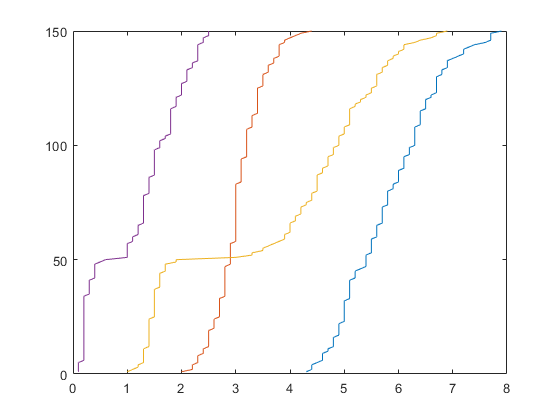

rng('default')
% rand(2,2);
[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexez= randperm(150);

plot(sort(meas()),(1:150))

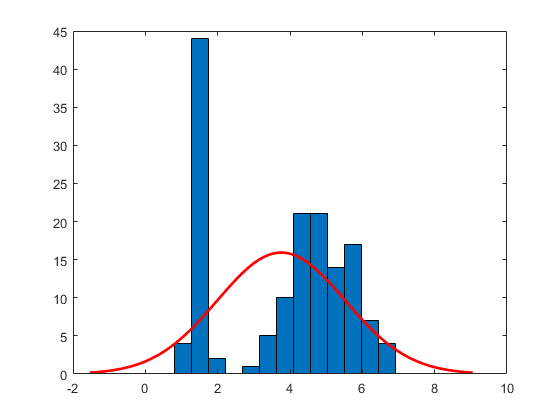

histfit((meas(:,3)))

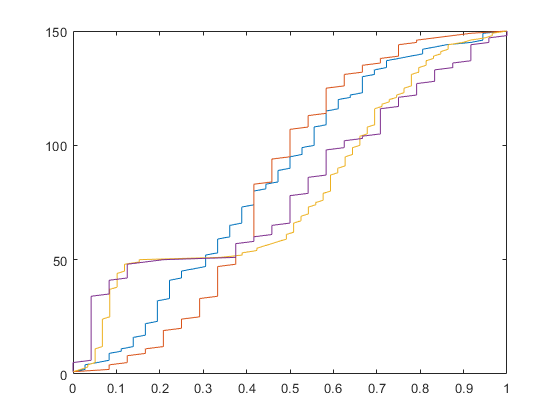


input = normalize(meas(indexez,:),'range');
plot(sort((input)), 1:150)

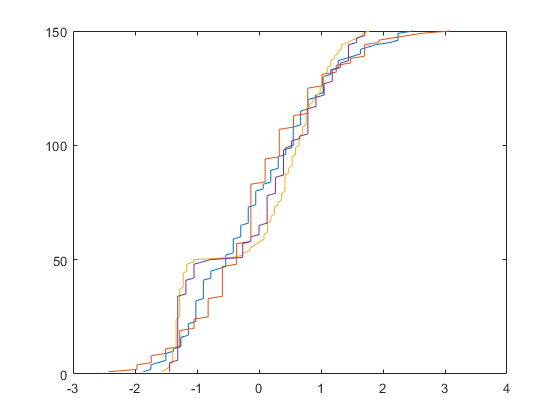


output = y(indexez,:);

input2 = normalize(meas(indexez,:));

g = (1 + exp(-1 * input2)) .^ -1;

plot(sort((input2)), 1:150)

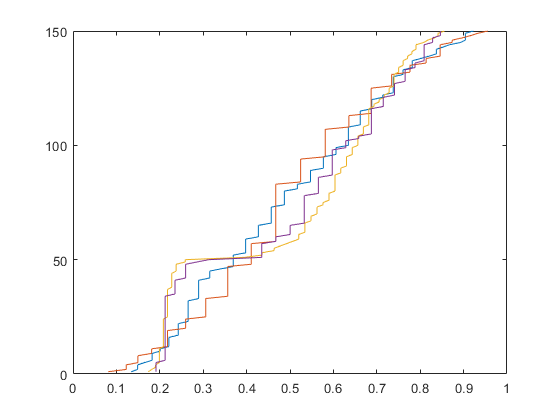

plot(sort((g)), 1:150)


testinput = g((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = g(1:batchsize,:);
out = output(1:batchsize,:);

n = 1;


knots = 10

knots = 10

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);

B=[];
C=[];


% Vandermonde ----------

for i = 1:batchsize
    
    index_a(i)= floor((in(i,1)*knots+(10*knots*eps)))+1;
    index_b(i)= floor((in(i,2)*knots+(10*knots*eps)))+1;
    index_c(i)= floor((in(i,3)*knots+(10*knots*eps)))+1;
    index_d(i)= floor((in(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(in(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(in(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(in(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(in(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,index_a(i):index_a(i)+2) = Ntemp_a;
    N_b(i,index_b(i):index_b(i)+2) = Ntemp_b;
    N_c(i,index_c(i):index_c(i)+2) = Ntemp_c;
    N_d(i,index_d(i):index_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
B(i,:)=f(:)';
    
% a=in(i,1).^[0:n];  % a = a/norm(a);
% b=in(i,2).^[0:n];  % b = b/norm(b);
% c=in(i,3).^[0:n];  % c = c/norm(c);
% d=in(i,4).^[0:n];  % d = d/norm(d);
% 
% f= outproduct(a,b,c,d);
% B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(knots+2)^4 3])/100;



alpha=1;

tic
for i= 1:100
z1 = B*w;

expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);
sum(p1,2);
% p1 = max(min(p1, 0.95),0.05);
d1 = p1-out;

tempo=(z1-alpha*d1)

w = pinv(B)*(tempo);
end

tempo =    -0.3351   -0.3335    0.6648
   -0.3336    0.6674   -0.3352
    0.6668   -0.3305   -0.3356
    0.6649   -0.3343   -0.3374
    0.6680   -0.3323   -0.3357
    0.6666   -0.3298   -0.3336
   -0.3341    0.6668   -0.3358
   -0.3347    0.6622   -0.3345
   -0.3319   -0.3324    0.6662
   -0.3328   -0.3315    0.6667


tempo =    -0.5472   -0.5456    1.0891
   -0.5458    1.0911   -0.5468
    1.0904   -0.5428   -0.5469
    1.0882   -0.5463   -0.5488
    1.0910   -0.5442   -0.5469
    1.0906   -0.5421   -0.5452
   -0.5463    1.0905   -0.5474
   -0.5473    1.0871   -0.5468
   -0.5443   -0.5443    1.0906
   -0.5450   -0.5436    1.0910


tempo =    -0.6876   -0.6859    1.3697
   -0.6861    1.3713   -0.6867
    1.3704   -0.6831   -0.6866
    1.3682   -0.6864   -0.6886
    1.3708   -0.6842   -0.6866
    1.3708   -0.6825   -0.6851
   -0.6866    1.3708   -0.6873
   -0.6879    1.3680   -0.6872
   -0.6848   -0.6846    1.3714
   -0.6854   -0.6839    1.3717


tempo =    -0.7896   -0.7878    1.5737
   -0.7881    1.5750   -0.7883
    1.5739   -0.7851   -0.7882
    1.5716   -0.7882   -0.7902
    1.5741   -0.7860   -0.7881
    1.5744   -0.7844   -0.7867
   -0.7886    1.5744   -0.7889
   -0.7900    1.5720   -0.7891
   -0.7869   -0.7865    1.5754
   -0.7874   -0.7858    1.5757


tempo =    -0.8690   -0.8672    1.7324
   -0.8675    1.7335   -0.8675
    1.7323   -0.8644   -0.8672
    1.7300   -0.8675   -0.8692
    1.7325   -0.8653   -0.8672
    1.7329   -0.8638   -0.8658
   -0.8680    1.7330   -0.8681
   -0.8694    1.7308   -0.8684
   -0.8664   -0.8658    1.7342
   -0.8668   -0.8652    1.7344


tempo =    -0.9338   -0.9319    1.8619
   -0.9323    1.8629   -0.9320
    1.8615   -0.9291   -0.9317
    1.8591   -0.9322   -0.9338
    1.8616   -0.9300   -0.9317
    1.8621   -0.9285   -0.9304
   -0.9328    1.8623   -0.9326
   -0.9343    1.8603   -0.9330
   -0.9313   -0.9305    1.8637
   -0.9316   -0.9299    1.8640


tempo =    -0.9884   -0.9865    1.9711
   -0.9869    1.9719   -0.9865
    1.9704   -0.9837   -0.9861
    1.9680   -0.9867   -0.9881
    1.9705   -0.9845   -0.9860
    1.9711   -0.9830   -0.9848
   -0.9874    1.9713   -0.9870
   -0.9889    1.9694   -0.9875
   -0.9859   -0.9850    1.9729
   -0.9862   -0.9845    1.9731


tempo =    -1.0355   -1.0336    2.0653
   -1.0340    2.0660   -1.0334
    2.0645   -1.0308   -1.0330
    2.0620   -1.0338   -1.0351
    2.0645   -1.0315   -1.0330
    2.0651   -1.0301   -1.0317
   -1.0345    2.0654   -1.0340
   -1.0360    2.0636   -1.0346
   -1.0331   -1.0321    2.0671
   -1.0334   -1.0316    2.0674


tempo =    -1.0769   -1.0750    2.1482
   -1.0755    2.1487   -1.0747
    2.1471   -1.0722   -1.0743
    2.1447   -1.0751   -1.0764
    2.1471   -1.0729   -1.0742
    2.1478   -1.0715   -1.0730
   -1.0760    2.1482   -1.0753
   -1.0775    2.1464   -1.0759
   -1.0745   -1.0735    2.1500
   -1.0748   -1.0730    2.1502


tempo =    -1.1139   -1.1119    2.2221
   -1.1124    2.2225   -1.1116
    2.2209   -1.1091   -1.1111
    2.2184   -1.1121   -1.1132
    2.2208   -1.1098   -1.1110
    2.2216   -1.1084   -1.1099
   -1.1129    2.2220   -1.1121
   -1.1145    2.2202   -1.1128
   -1.1115   -1.1104    2.2239
   -1.1118   -1.1099    2.2241


tempo =    -1.1473   -1.1452    2.2887
   -1.1458    2.2891   -1.1448
    2.2874   -1.1424   -1.1443
    2.2849   -1.1453   -1.1464
    2.2873   -1.1431   -1.1442
    2.2881   -1.1418   -1.1431
   -1.1463    2.2886   -1.1454
   -1.1478    2.2869   -1.1461
   -1.1449   -1.1437    2.2906
   -1.1451   -1.1432    2.2908


tempo =    -1.1776   -1.1756    2.3494
   -1.1761    2.3498   -1.1751
    2.3479   -1.1727   -1.1745
    2.3455   -1.1757   -1.1766
    2.3479   -1.1734   -1.1745
    2.3487   -1.1721   -1.1733
   -1.1767    2.3492   -1.1756
   -1.1782    2.3475   -1.1764
   -1.1753   -1.1740    2.3513
   -1.1755   -1.1735    2.3515


tempo =    -1.2055   -1.2034    2.4052
   -1.2040    2.4054   -1.2029
    2.4035   -1.2006   -1.2023
    2.4011   -1.2035   -1.2044
    2.4034   -1.2012   -1.2023
    2.4043   -1.1999   -1.2011
   -1.2045    2.4049   -1.2034
   -1.2061    2.4032   -1.2042
   -1.2032   -1.2019    2.4070
   -1.2034   -1.2014    2.4072


tempo =    -1.2313   -1.2291    2.4566
   -1.2298    2.4569   -1.2285
    2.4549   -1.2263   -1.2279
    2.4525   -1.2292   -1.2301
    2.4548   -1.2269   -1.2279
    2.4557   -1.2256   -1.2268
   -1.2303    2.4563   -1.2291
   -1.2318    2.4547   -1.2299
   -1.2289   -1.2276    2.4585
   -1.2292   -1.2271    2.4587


tempo =    -1.2552   -1.2530    2.5045
   -1.2537    2.5047   -1.2524
    2.5027   -1.2502   -1.2518
    2.5002   -1.2531   -1.2539
    2.5025   -1.2508   -1.2517
    2.5034   -1.2495   -1.2506
   -1.2543    2.5041   -1.2530
   -1.2558    2.5025   -1.2538
   -1.2529   -1.2515    2.5064
   -1.2531   -1.2510    2.5065


tempo =    -1.2776   -1.2754    2.5492
   -1.2761    2.5493   -1.2747
    2.5472   -1.2725   -1.2740
    2.5448   -1.2754   -1.2762
    2.5471   -1.2731   -1.2740
    2.5480   -1.2719   -1.2729
   -1.2766    2.5488   -1.2752
   -1.2782    2.5472   -1.2761
   -1.2753   -1.2738    2.5510
   -1.2755   -1.2733    2.5512


tempo =    -1.2985   -1.2963    2.5911
   -1.2971    2.5912   -1.2956
    2.5891   -1.2935   -1.2949
    2.5866   -1.2963   -1.2971
    2.5889   -1.2941   -1.2949
    2.5898   -1.2928   -1.2938
   -1.2976    2.5906   -1.2961
   -1.2991    2.5891   -1.2970
   -1.2962   -1.2947    2.5930
   -1.2964   -1.2943    2.5931


tempo =    -1.3183   -1.3160    2.6305
   -1.3168    2.6306   -1.3153
    2.6284   -1.3132   -1.3146
    2.6260   -1.3160   -1.3167
    2.6283   -1.3138   -1.3146
    2.6292   -1.3125   -1.3134
   -1.3173    2.6301   -1.3158
   -1.3189    2.6285   -1.3167
   -1.3160   -1.3144    2.6324
   -1.3162   -1.3140    2.6326


tempo =    -1.3369   -1.3346    2.6678
   -1.3355    2.6679   -1.3338
    2.6656   -1.3318   -1.3331
    2.6632   -1.3347   -1.3353
    2.6655   -1.3324   -1.3331
    2.6664   -1.3311   -1.3320
   -1.3360    2.6673   -1.3344
   -1.3375    2.6658   -1.3353
   -1.3347   -1.3331    2.6697
   -1.3348   -1.3326    2.6699


tempo =    -1.3546   -1.3523    2.7032
   -1.3532    2.7032   -1.3515
    2.7009   -1.3494   -1.3507
    2.6984   -1.3523   -1.3529
    2.7007   -1.3500   -1.3507
    2.7017   -1.3488   -1.3496
   -1.3537    2.7026   -1.3520
   -1.3552    2.7011   -1.3529
   -1.3523   -1.3507    2.7050
   -1.3525   -1.3503    2.7052


tempo =    -1.3714   -1.3691    2.7367
   -1.3700    2.7367   -1.3682
    2.7344   -1.3662   -1.3675
    2.7319   -1.3691   -1.3697
    2.7342   -1.3668   -1.3675
    2.7352   -1.3655   -1.3664
   -1.3705    2.7361   -1.3688
   -1.3720    2.7346   -1.3696
   -1.3691   -1.3675    2.7386
   -1.3693   -1.3670    2.7388


tempo =    -1.3874   -1.3850    2.7687
   -1.3860    2.7686   -1.3841
    2.7663   -1.3822   -1.3834
    2.7638   -1.3850   -1.3856
    2.7661   -1.3827   -1.3834
    2.7671   -1.3815   -1.3823
   -1.3865    2.7681   -1.3847
   -1.3880    2.7666   -1.3856
   -1.3852   -1.3834    2.7706
   -1.3853   -1.3830    2.7707


tempo =    -1.4027   -1.4003    2.7992
   -1.4012    2.7991   -1.3994
    2.7967   -1.3974   -1.3986
    2.7942   -1.4003   -1.4008
    2.7966   -1.3980   -1.3986
    2.7975   -1.3968   -1.3975
   -1.4018    2.7986   -1.3999
   -1.4033    2.7971   -1.4008
   -1.4004   -1.3987    2.8011
   -1.4006   -1.3982    2.8013


tempo =    -1.4173   -1.4149    2.8284
   -1.4158    2.8283   -1.4139
    2.8258   -1.4120   -1.4131
    2.8234   -1.4148   -1.4153
    2.8257   -1.4126   -1.4131
    2.8266   -1.4113   -1.4120
   -1.4164    2.8278   -1.4145
   -1.4179    2.8263   -1.4154
   -1.4150   -1.4133    2.8303
   -1.4152   -1.4128    2.8305


tempo =    -1.4313   -1.4288    2.8564
   -1.4298    2.8563   -1.4279
    2.8538   -1.4260   -1.4271
    2.8513   -1.4288   -1.4293
    2.8536   -1.4265   -1.4271
    2.8546   -1.4253   -1.4260
   -1.4304    2.8557   -1.4284
   -1.4319    2.8542   -1.4293
   -1.4291   -1.4272    2.8583
   -1.4292   -1.4268    2.8584


tempo =    -1.4447   -1.4423    2.8833
   -1.4433    2.8831   -1.4413
    2.8806   -1.4394   -1.4405
    2.8781   -1.4422   -1.4427
    2.8804   -1.4399   -1.4405
    2.8814   -1.4387   -1.4394
   -1.4438    2.8826   -1.4418
   -1.4454    2.8811   -1.4428
   -1.4425   -1.4406    2.8851
   -1.4426   -1.4402    2.8853


tempo =    -1.4577   -1.4552    2.9091
   -1.4562    2.9089   -1.4542
    2.9063   -1.4523   -1.4533
    2.9039   -1.4551   -1.4556
    2.9062   -1.4528   -1.4534
    2.9071   -1.4516   -1.4523
   -1.4567    2.9084   -1.4547
   -1.4583    2.9069   -1.4556
   -1.4554   -1.4535    2.9110
   -1.4556   -1.4531    2.9111


tempo =    -1.4701   -1.4676    2.9340
   -1.4687    2.9338   -1.4666
    2.9312   -1.4647   -1.4657
    2.9287   -1.4675   -1.4679
    2.9310   -1.4653   -1.4657
    2.9320   -1.4641   -1.4647
   -1.4692    2.9332   -1.4671
   -1.4707    2.9318   -1.4681
   -1.4679   -1.4660    2.9358
   -1.4680   -1.4656    2.9360


tempo =    -1.4821   -1.4796    2.9579
   -1.4807    2.9577   -1.4785
    2.9551   -1.4767   -1.4777
    2.9526   -1.4795   -1.4799
    2.9549   -1.4772   -1.4777
    2.9559   -1.4760   -1.4766
   -1.4812    2.9572   -1.4791
   -1.4827    2.9557   -1.4800
   -1.4799   -1.4779    2.9598
   -1.4800   -1.4775    2.9600


tempo =    -1.4937   -1.4911    2.9811
   -1.4923    2.9809   -1.4901
    2.9782   -1.4883   -1.4892
    2.9757   -1.4911   -1.4914
    2.9780   -1.4888   -1.4892
    2.9790   -1.4876   -1.4881
   -1.4928    2.9803   -1.4906
   -1.4943    2.9789   -1.4916
   -1.4915   -1.4895    2.9830
   -1.4916   -1.4891    2.9832


tempo =    -1.5049   -1.5023    3.0035
   -1.5035    3.0032   -1.5012
    3.0005   -1.4995   -1.5004
    2.9980   -1.5023   -1.5026
    3.0003   -1.5000   -1.5004
    3.0013   -1.4988   -1.4993
   -1.5040    3.0027   -1.5018
   -1.5055    3.0013   -1.5027
   -1.5027   -1.5007    3.0054
   -1.5028   -1.5003    3.0055


tempo =    -1.5158   -1.5131    3.0252
   -1.5143    3.0249   -1.5120
    3.0221   -1.5103   -1.5112
    3.0197   -1.5131   -1.5134
    3.0220   -1.5108   -1.5112
    3.0230   -1.5096   -1.5101
   -1.5148    3.0243   -1.5126
   -1.5164    3.0229   -1.5135
   -1.5135   -1.5115    3.0270
   -1.5137   -1.5111    3.0272


tempo =    -1.5263   -1.5236    3.0461
   -1.5248    3.0459   -1.5225
    3.0431   -1.5208   -1.5216
    3.0406   -1.5236   -1.5239
    3.0429   -1.5213   -1.5216
    3.0439   -1.5201   -1.5206
   -1.5254    3.0453   -1.5231
   -1.5269    3.0439   -1.5240
   -1.5241   -1.5220    3.0480
   -1.5242   -1.5216    3.0482


tempo =    -1.5365   -1.5338    3.0665
   -1.5350    3.0662   -1.5326
    3.0634   -1.5309   -1.5318
    3.0609   -1.5337   -1.5340
    3.0632   -1.5314   -1.5318
    3.0642   -1.5302   -1.5307
   -1.5355    3.0657   -1.5332
   -1.5371    3.0642   -1.5342
   -1.5342   -1.5322    3.0684
   -1.5343   -1.5318    3.0685


tempo =    -1.5463   -1.5437    3.0862
   -1.5449    3.0859   -1.5425
    3.0831   -1.5408   -1.5416
    3.0806   -1.5436   -1.5438
    3.0829   -1.5413   -1.5416
    3.0839   -1.5401   -1.5405
   -1.5454    3.0854   -1.5431
   -1.5470    3.0840   -1.5440
   -1.5441   -1.5420    3.0881
   -1.5442   -1.5416    3.0883


tempo =    -1.5559   -1.5532    3.1054
   -1.5545    3.1051   -1.5521
    3.1022   -1.5504   -1.5512
    3.0998   -1.5532   -1.5534
    3.1020   -1.5509   -1.5512
    3.1030   -1.5497   -1.5501
   -1.5550    3.1046   -1.5526
   -1.5566    3.1031   -1.5536
   -1.5537   -1.5516    3.1073
   -1.5538   -1.5512    3.1075


tempo =    -1.5653   -1.5626    3.1241
   -1.5638    3.1237   -1.5614
    3.1208   -1.5597   -1.5605
    3.1184   -1.5625   -1.5627
    3.1207   -1.5602   -1.5605
    3.1217   -1.5590   -1.5594
   -1.5644    3.1232   -1.5619
   -1.5659    3.1218   -1.5629
   -1.5631   -1.5609    3.1260
   -1.5632   -1.5605    3.1261


tempo =    -1.5744   -1.5716    3.1422
   -1.5729    3.1419   -1.5704
    3.1389   -1.5687   -1.5695
    3.1365   -1.5715   -1.5717
    3.1388   -1.5692   -1.5695
    3.1398   -1.5681   -1.5684
   -1.5735    3.1413   -1.5710
   -1.5750    3.1399   -1.5720
   -1.5722   -1.5700    3.1441
   -1.5723   -1.5696    3.1443


tempo =    -1.5832   -1.5805    3.1599
   -1.5818    3.1595   -1.5792
    3.1566   -1.5776   -1.5783
    3.1541   -1.5804   -1.5805
    3.1564   -1.5781   -1.5783
    3.1574   -1.5769   -1.5773
   -1.5823    3.1590   -1.5798
   -1.5838    3.1576   -1.5808
   -1.5810   -1.5788    3.1618
   -1.5811   -1.5784    3.1620


tempo =    -1.5918   -1.5891    3.1771
   -1.5904    3.1767   -1.5878
    3.1738   -1.5862   -1.5869
    3.1713   -1.5889   -1.5891
    3.1736   -1.5867   -1.5869
    3.1746   -1.5855   -1.5858
   -1.5909    3.1762   -1.5884
   -1.5924    3.1748   -1.5894
   -1.5896   -1.5874    3.1790
   -1.5897   -1.5870    3.1792


tempo =    -1.6002   -1.5974    3.1939
   -1.5988    3.1935   -1.5962
    3.1905   -1.5946   -1.5952
    3.1880   -1.5973   -1.5975
    3.1903   -1.5950   -1.5953
    3.1913   -1.5939   -1.5942
   -1.5993    3.1930   -1.5967
   -1.6008    3.1916   -1.5977
   -1.5980   -1.5958    3.1958
   -1.5981   -1.5954    3.1960


tempo =    -1.6084   -1.6056    3.2103
   -1.6070    3.2099   -1.6043
    3.2068   -1.6027   -1.6034
    3.2043   -1.6055   -1.6057
    3.2066   -1.6032   -1.6034
    3.2077   -1.6020   -1.6024
   -1.6075    3.2093   -1.6049
   -1.6090    3.2079   -1.6059
   -1.6062   -1.6040    3.2122
   -1.6063   -1.6036    3.2123


tempo =    -1.6164   -1.6136    3.2263
   -1.6150    3.2258   -1.6123
    3.2228   -1.6107   -1.6114
    3.2203   -1.6135   -1.6136
    3.2226   -1.6112   -1.6114
    3.2236   -1.6100   -1.6103
   -1.6155    3.2253   -1.6129
   -1.6170    3.2239   -1.6139
   -1.6142   -1.6119    3.2282
   -1.6143   -1.6116    3.2283


tempo =    -1.6242   -1.6214    3.2419
   -1.6228    3.2414   -1.6201
    3.2384   -1.6185   -1.6191
    3.2359   -1.6213   -1.6214
    3.2382   -1.6190   -1.6192
    3.2392   -1.6178   -1.6181
   -1.6233    3.2409   -1.6207
   -1.6248    3.2395   -1.6217
   -1.6220   -1.6197    3.2438
   -1.6221   -1.6194    3.2439


tempo =    -1.6319   -1.6290    3.2571
   -1.6304    3.2567   -1.6277
    3.2536   -1.6261   -1.6267
    3.2511   -1.6289   -1.6290
    3.2534   -1.6266   -1.6268
    3.2544   -1.6254   -1.6257
   -1.6310    3.2561   -1.6283
   -1.6325    3.2547   -1.6293
   -1.6297   -1.6274    3.2590
   -1.6298   -1.6270    3.2592


tempo =    -1.6393   -1.6365    3.2720
   -1.6379    3.2716   -1.6351
    3.2685   -1.6336   -1.6342
    3.2660   -1.6363   -1.6364
    3.2683   -1.6341   -1.6342
    3.2693   -1.6329   -1.6331
   -1.6384    3.2710   -1.6357
   -1.6399    3.2696   -1.6367
   -1.6371   -1.6348    3.2739
   -1.6372   -1.6344    3.2741


tempo =    -1.6466   -1.6438    3.2866
   -1.6452    3.2862   -1.6424
    3.2830   -1.6409   -1.6414
    3.2805   -1.6436   -1.6437
    3.2828   -1.6413   -1.6415
    3.2838   -1.6402   -1.6404
   -1.6457    3.2856   -1.6430
   -1.6473    3.2842   -1.6440
   -1.6445   -1.6421    3.2885
   -1.6445   -1.6417    3.2887


tempo =    -1.6538   -1.6509    3.3009
   -1.6524    3.3004   -1.6495
    3.2973   -1.6480   -1.6486
    3.2948   -1.6508   -1.6508
    3.2971   -1.6485   -1.6486
    3.2981   -1.6473   -1.6475
   -1.6529    3.2999   -1.6501
   -1.6544    3.2985   -1.6511
   -1.6516   -1.6492    3.3028
   -1.6517   -1.6489    3.3030


tempo =    -1.6608   -1.6579    3.3149
   -1.6594    3.3144   -1.6565
    3.3112   -1.6550   -1.6555
    3.3087   -1.6577   -1.6578
    3.3110   -1.6555   -1.6556
    3.3120   -1.6543   -1.6545
   -1.6599    3.3139   -1.6571
   -1.6614    3.3125   -1.6581
   -1.6586   -1.6562    3.3168
   -1.6587   -1.6558    3.3170


tempo =    -1.6676   -1.6647    3.3286
   -1.6662    3.3281   -1.6633
    3.3249   -1.6618   -1.6624
    3.3224   -1.6646   -1.6646
    3.3247   -1.6623   -1.6624
    3.3257   -1.6611   -1.6613
   -1.6667    3.3276   -1.6639
   -1.6683    3.3262   -1.6649
   -1.6655   -1.6630    3.3305
   -1.6655   -1.6627    3.3307


tempo =    -1.6744   -1.6714    3.3420
   -1.6729    3.3415   -1.6700
    3.3383   -1.6685   -1.6690
    3.3358   -1.6713   -1.6713
    3.3381   -1.6690   -1.6691
    3.3391   -1.6678   -1.6680
   -1.6735    3.3410   -1.6706
   -1.6750    3.3396   -1.6716
   -1.6722   -1.6697    3.3439
   -1.6723   -1.6694    3.3441


tempo =    -1.6809   -1.6780    3.3552
   -1.6795    3.3547   -1.6766
    3.3514   -1.6751   -1.6756
    3.3489   -1.6779   -1.6779
    3.3512   -1.6756   -1.6756
    3.3522   -1.6744   -1.6746
   -1.6800    3.3541   -1.6772
   -1.6816    3.3527   -1.6782
   -1.6788   -1.6763    3.3571
   -1.6788   -1.6760    3.3572


tempo =    -1.6874   -1.6844    3.3681
   -1.6860    3.3675   -1.6830
    3.3643   -1.6815   -1.6820
    3.3618   -1.6843   -1.6843
    3.3641   -1.6820   -1.6821
    3.3651   -1.6808   -1.6810
   -1.6865    3.3670   -1.6836
   -1.6880    3.3656   -1.6846
   -1.6852   -1.6828    3.3700
   -1.6853   -1.6824    3.3701


tempo =    -1.6937   -1.6908    3.3807
   -1.6923    3.3802   -1.6893
    3.3769   -1.6879   -1.6883
    3.3744   -1.6906   -1.6906
    3.3767   -1.6883   -1.6884
    3.3777   -1.6872   -1.6873
   -1.6928    3.3797   -1.6899
   -1.6944    3.3783   -1.6909
   -1.6916   -1.6891    3.3826
   -1.6916   -1.6887    3.3828


tempo =    -1.7000   -1.6970    3.3932
   -1.6985    3.3926   -1.6955
    3.3893   -1.6941   -1.6945
    3.3868   -1.6968   -1.6968
    3.3891   -1.6945   -1.6946
    3.3901   -1.6934   -1.6935
   -1.6991    3.3921   -1.6961
   -1.7006    3.3907   -1.6971
   -1.6978   -1.6953    3.3951
   -1.6979   -1.6949    3.3952


tempo =    -1.7061   -1.7031    3.4054
   -1.7046    3.4048   -1.7016
    3.4015   -1.7002   -1.7006
    3.3990   -1.7029   -1.7029
    3.4013   -1.7006   -1.7007
    3.4023   -1.6995   -1.6996
   -1.7052    3.4043   -1.7022
   -1.7067    3.4029   -1.7032
   -1.7039   -1.7014    3.4073
   -1.7040   -1.7010    3.4074


tempo =    -1.7121   -1.7090    3.4174
   -1.7106    3.4168   -1.7076
    3.4134   -1.7061   -1.7066
    3.4109   -1.7089   -1.7088
    3.4132   -1.7066   -1.7066
    3.4143   -1.7054   -1.7055
   -1.7112    3.4162   -1.7082
   -1.7127    3.4149   -1.7092
   -1.7099   -1.7074    3.4193
   -1.7100   -1.7070    3.4194


tempo =    -1.7180   -1.7149    3.4291
   -1.7165    3.4285   -1.7135
    3.4252   -1.7120   -1.7124
    3.4227   -1.7148   -1.7147
    3.4250   -1.7125   -1.7125
    3.4260   -1.7113   -1.7114
   -1.7171    3.4280   -1.7140
   -1.7186    3.4266   -1.7151
   -1.7158   -1.7132    3.4310
   -1.7159   -1.7129    3.4312


tempo =    -1.7237   -1.7207    3.4407
   -1.7223    3.4401   -1.7192
    3.4367   -1.7178   -1.7182
    3.4342   -1.7205   -1.7205
    3.4365   -1.7183   -1.7183
    3.4375   -1.7171   -1.7172
   -1.7229    3.4396   -1.7198
   -1.7244    3.4382   -1.7208
   -1.7216   -1.7190    3.4426
   -1.7216   -1.7187    3.4428


tempo =    -1.7294   -1.7264    3.4521
   -1.7280    3.4515   -1.7249
    3.4480   -1.7235   -1.7239
    3.4456   -1.7262   -1.7261
    3.4478   -1.7239   -1.7239
    3.4489   -1.7228   -1.7228
   -1.7285    3.4509   -1.7255
   -1.7301    3.4495   -1.7265
   -1.7273   -1.7247    3.4540
   -1.7273   -1.7243    3.4541


tempo =    -1.7350   -1.7320    3.4632
   -1.7336    3.4626   -1.7305
    3.4592   -1.7291   -1.7294
    3.4567   -1.7318   -1.7317
    3.4590   -1.7295   -1.7295
    3.4600   -1.7284   -1.7284
   -1.7341    3.4621   -1.7310
   -1.7356    3.4607   -1.7321
   -1.7329   -1.7303    3.4651
   -1.7329   -1.7299    3.4653


tempo =    -1.7405   -1.7375    3.4742
   -1.7391    3.4736   -1.7360
    3.4702   -1.7346   -1.7349
    3.4677   -1.7373   -1.7372
    3.4700   -1.7350   -1.7350
    3.4710   -1.7338   -1.7339
   -1.7397    3.4731   -1.7365
   -1.7412    3.4717   -1.7376
   -1.7384   -1.7358    3.4761
   -1.7384   -1.7354    3.4763


tempo =    -1.7460   -1.7429    3.4851
   -1.7445    3.4844   -1.7414
    3.4810   -1.7400   -1.7403
    3.4785   -1.7427   -1.7426
    3.4808   -1.7404   -1.7404
    3.4818   -1.7392   -1.7393
   -1.7451    3.4839   -1.7419
   -1.7466    3.4825   -1.7430
   -1.7438   -1.7412    3.4870
   -1.7439   -1.7408    3.4871


tempo =    -1.7513   -1.7482    3.4957
   -1.7499    3.4951   -1.7467
    3.4916   -1.7453   -1.7456
    3.4891   -1.7480   -1.7479
    3.4914   -1.7457   -1.7457
    3.4924   -1.7446   -1.7446
   -1.7504    3.4945   -1.7472
   -1.7519    3.4932   -1.7483
   -1.7491   -1.7465    3.4976
   -1.7492   -1.7461    3.4978


tempo =    -1.7565   -1.7534    3.5062
   -1.7551    3.5055   -1.7519
    3.5020   -1.7505   -1.7508
    3.4995   -1.7532   -1.7531
    3.5018   -1.7510   -1.7509
    3.5029   -1.7498   -1.7498
   -1.7556    3.5050   -1.7524
   -1.7571    3.5036   -1.7535
   -1.7544   -1.7517    3.5081
   -1.7544   -1.7514    3.5082


tempo =    -1.7617   -1.7586    3.5165
   -1.7603    3.5159   -1.7570
    3.5123   -1.7557   -1.7560
    3.5098   -1.7584   -1.7583
    3.5121   -1.7561   -1.7560
    3.5132   -1.7549   -1.7550
   -1.7608    3.5153   -1.7576
   -1.7623    3.5139   -1.7586
   -1.7595   -1.7569    3.5184
   -1.7596   -1.7565    3.5186


tempo =    -1.7668   -1.7636    3.5267
   -1.7654    3.5260   -1.7621
    3.5225   -1.7607   -1.7610
    3.5200   -1.7635   -1.7633
    3.5223   -1.7612   -1.7611
    3.5233   -1.7600   -1.7600
   -1.7659    3.5255   -1.7627
   -1.7674    3.5241   -1.7637
   -1.7646   -1.7620    3.5286
   -1.7647   -1.7616    3.5287


tempo =    -1.7718   -1.7686    3.5367
   -1.7704    3.5360   -1.7671
    3.5325   -1.7657   -1.7660
    3.5300   -1.7685   -1.7683
    3.5322   -1.7662   -1.7661
    3.5333   -1.7650   -1.7650
   -1.7709    3.5355   -1.7677
   -1.7724    3.5341   -1.7687
   -1.7696   -1.7670    3.5386
   -1.7697   -1.7666    3.5387


tempo =    -1.7767   -1.7736    3.5465
   -1.7753    3.5459   -1.7720
    3.5423   -1.7707   -1.7709
    3.5398   -1.7734   -1.7732
    3.5421   -1.7711   -1.7710
    3.5431   -1.7699   -1.7699
   -1.7758    3.5453   -1.7726
   -1.7773    3.5440   -1.7736
   -1.7746   -1.7719    3.5484
   -1.7746   -1.7715    3.5486


tempo =    -1.7816   -1.7784    3.5563
   -1.7802    3.5556   -1.7769
    3.5520   -1.7755   -1.7758
    3.5495   -1.7782   -1.7781
    3.5518   -1.7760   -1.7758
    3.5528   -1.7748   -1.7748
   -1.7807    3.5550   -1.7774
   -1.7822    3.5537   -1.7785
   -1.7794   -1.7767    3.5582
   -1.7795   -1.7764    3.5583


tempo =    -1.7864   -1.7832    3.5658
   -1.7850    3.5651   -1.7816
    3.5616   -1.7803   -1.7806
    3.5591   -1.7830   -1.7828
    3.5613   -1.7807   -1.7806
    3.5624   -1.7796   -1.7795
   -1.7855    3.5646   -1.7822
   -1.7870    3.5632   -1.7832
   -1.7842   -1.7815    3.5677
   -1.7843   -1.7812    3.5679


tempo =    -1.7911   -1.7879    3.5753
   -1.7897    3.5746   -1.7863
    3.5710   -1.7850   -1.7853
    3.5685   -1.7877   -1.7876
    3.5708   -1.7855   -1.7853
    3.5718   -1.7843   -1.7843
   -1.7902    3.5740   -1.7869
   -1.7917    3.5727   -1.7880
   -1.7890   -1.7862    3.5772
   -1.7890   -1.7859    3.5773


tempo =    -1.7958   -1.7926    3.5846
   -1.7944    3.5839   -1.7910
    3.5803   -1.7897   -1.7899
    3.5778   -1.7924   -1.7922
    3.5800   -1.7901   -1.7900
    3.5811   -1.7889   -1.7889
   -1.7949    3.5833   -1.7915
   -1.7964    3.5820   -1.7926
   -1.7936   -1.7909    3.5865
   -1.7937   -1.7905    3.5867


tempo =    -1.8004   -1.7972    3.5938
   -1.7990    3.5931   -1.7956
    3.5894   -1.7942   -1.7945
    3.5869   -1.7970   -1.7968
    3.5892   -1.7947   -1.7945
    3.5903   -1.7935   -1.7935
   -1.7995    3.5925   -1.7961
   -1.8010    3.5912   -1.7972
   -1.7982   -1.7955    3.5957
   -1.7983   -1.7951    3.5958


tempo =    -1.8049   -1.8017    3.6028
   -1.8035    3.6021   -1.8001
    3.5985   -1.7988   -1.7990
    3.5960   -1.8015   -1.8013
    3.5982   -1.7992   -1.7991
    3.5993   -1.7981   -1.7980
   -1.8040    3.6016   -1.8006
   -1.8055    3.6002   -1.8017
   -1.8028   -1.8000    3.6047
   -1.8028   -1.7997    3.6049


tempo =    -1.8094   -1.8062    3.6118
   -1.8080    3.6111   -1.8045
    3.6074   -1.8032   -1.8034
    3.6049   -1.8060   -1.8057
    3.6072   -1.8037   -1.8035
    3.6082   -1.8025   -1.8024
   -1.8085    3.6105   -1.8051
   -1.8100    3.6092   -1.8062
   -1.8072   -1.8045    3.6137
   -1.8073   -1.8041    3.6138


tempo =    -1.8138   -1.8106    3.6206
   -1.8124    3.6199   -1.8089
    3.6162   -1.8076   -1.8078
    3.6137   -1.8104   -1.8101
    3.6160   -1.8081   -1.8079
    3.6170   -1.8069   -1.8068
   -1.8129    3.6193   -1.8095
   -1.8144    3.6180   -1.8106
   -1.8117   -1.8089    3.6225
   -1.8117   -1.8085    3.6227


tempo =    -1.8182   -1.8149    3.6293
   -1.8168    3.6286   -1.8133
    3.6249   -1.8120   -1.8122
    3.6224   -1.8147   -1.8145
    3.6247   -1.8124   -1.8122
    3.6257   -1.8113   -1.8112
   -1.8173    3.6280   -1.8138
   -1.8188    3.6267   -1.8149
   -1.8160   -1.8132    3.6312
   -1.8161   -1.8129    3.6314


tempo =    -1.8225   -1.8192    3.6379
   -1.8211    3.6372   -1.8176
    3.6334   -1.8163   -1.8165
    3.6310   -1.8190   -1.8188
    3.6332   -1.8167   -1.8165
    3.6343   -1.8156   -1.8155
   -1.8216    3.6366   -1.8181
   -1.8231    3.6353   -1.8192
   -1.8203   -1.8175    3.6398
   -1.8204   -1.8172    3.6400


tempo =    -1.8267   -1.8234    3.6464
   -1.8253    3.6456   -1.8218
    3.6419   -1.8205   -1.8207
    3.6394   -1.8232   -1.8230
    3.6417   -1.8210   -1.8208
    3.6427   -1.8198   -1.8197
   -1.8258    3.6451   -1.8224
   -1.8273    3.6437   -1.8234
   -1.8246   -1.8217    3.6483
   -1.8246   -1.8214    3.6485


tempo =    -1.8309   -1.8276    3.6548
   -1.8295    3.6540   -1.8260
    3.6503   -1.8247   -1.8249
    3.6478   -1.8274   -1.8272
    3.6501   -1.8251   -1.8249
    3.6511   -1.8240   -1.8239
   -1.8300    3.6535   -1.8265
   -1.8315    3.6521   -1.8276
   -1.8288   -1.8259    3.6567
   -1.8288   -1.8256    3.6568


tempo =    -1.8350   -1.8318    3.6630
   -1.8336    3.6623   -1.8301
    3.6585   -1.8288   -1.8290
    3.6560   -1.8316   -1.8313
    3.6583   -1.8293   -1.8291
    3.6594   -1.8281   -1.8280
   -1.8342    3.6617   -1.8307
   -1.8357    3.6604   -1.8317
   -1.8329   -1.8301    3.6650
   -1.8330   -1.8297    3.6651


tempo =    -1.8391   -1.8358    3.6712
   -1.8377    3.6705   -1.8342
    3.6667   -1.8329   -1.8331
    3.6642   -1.8356   -1.8354
    3.6665   -1.8334   -1.8331
    3.6675   -1.8322   -1.8321
   -1.8383    3.6699   -1.8347
   -1.8398    3.6686   -1.8358
   -1.8370   -1.8341    3.6731
   -1.8370   -1.8338    3.6733


tempo =    -1.8432   -1.8399    3.6793
   -1.8418    3.6785   -1.8382
    3.6747   -1.8370   -1.8371
    3.6722   -1.8397   -1.8394
    3.6745   -1.8374   -1.8372
    3.6756   -1.8362   -1.8361
   -1.8423    3.6780   -1.8388
   -1.8438    3.6766   -1.8398
   -1.8410   -1.8382    3.6812
   -1.8411   -1.8378    3.6814


tempo =    -1.8472   -1.8439    3.6873
   -1.8458    3.6865   -1.8422
    3.6827   -1.8409   -1.8411
    3.6802   -1.8437   -1.8434
    3.6825   -1.8414   -1.8411
    3.6835   -1.8402   -1.8401
   -1.8463    3.6860   -1.8427
   -1.8478    3.6846   -1.8438
   -1.8450   -1.8422    3.6892
   -1.8451   -1.8418    3.6893


tempo =    -1.8511   -1.8478    3.6952
   -1.8497    3.6944   -1.8461
    3.6906   -1.8449   -1.8450
    3.6881   -1.8476   -1.8473
    3.6903   -1.8453   -1.8451
    3.6914   -1.8442   -1.8440
   -1.8503    3.6938   -1.8467
   -1.8517    3.6925   -1.8477
   -1.8490   -1.8461    3.6971
   -1.8490   -1.8458    3.6972


tempo =    -1.8550   -1.8517    3.7030
   -1.8536    3.7022   -1.8500
    3.6983   -1.8488   -1.8489
    3.6958   -1.8515   -1.8512
    3.6981   -1.8492   -1.8490
    3.6992   -1.8480   -1.8479
   -1.8542    3.7016   -1.8506
   -1.8556    3.7003   -1.8516
   -1.8529   -1.8500    3.7049
   -1.8529   -1.8497    3.7050


tempo =    -1.8589   -1.8555    3.7107
   -1.8575    3.7099   -1.8538
    3.7060   -1.8526   -1.8527
    3.7035   -1.8553   -1.8550
    3.7058   -1.8530   -1.8528
    3.7069   -1.8519   -1.8517
   -1.8580    3.7093   -1.8544
   -1.8595    3.7080   -1.8555
   -1.8568   -1.8538    3.7126
   -1.8568   -1.8535    3.7127


tempo =    -1.8627   -1.8593    3.7183
   -1.8613    3.7175   -1.8576
    3.7136   -1.8564   -1.8565
    3.7111   -1.8591   -1.8588
    3.7134   -1.8568   -1.8566
    3.7145   -1.8557   -1.8555
   -1.8618    3.7169   -1.8582
   -1.8633    3.7156   -1.8593
   -1.8606   -1.8576    3.7202
   -1.8606   -1.8573    3.7203


tempo =    -1.8665   -1.8631    3.7258
   -1.8651    3.7250   -1.8614
    3.7211   -1.8602   -1.8603
    3.7186   -1.8629   -1.8626
    3.7209   -1.8606   -1.8603
    3.7220   -1.8595   -1.8593
   -1.8656    3.7245   -1.8620
   -1.8671    3.7231   -1.8630
   -1.8643   -1.8614    3.7277
   -1.8644   -1.8611    3.7279


tempo =    -1.8702   -1.8668    3.7333
   -1.8688    3.7324   -1.8651
    3.7286   -1.8639   -1.8640
    3.7261   -1.8666   -1.8663
    3.7283   -1.8643   -1.8640
    3.7294   -1.8632   -1.8630
   -1.8693    3.7319   -1.8657
   -1.8708    3.7305   -1.8667
   -1.8681   -1.8651    3.7352
   -1.8681   -1.8648    3.7353


tempo =    -1.8739   -1.8705    3.7406
   -1.8725    3.7398   -1.8688
    3.7359   -1.8676   -1.8676
    3.7334   -1.8703   -1.8699
    3.7357   -1.8680   -1.8677
    3.7368   -1.8669   -1.8666
   -1.8730    3.7393   -1.8693
   -1.8745    3.7379   -1.8704
   -1.8718   -1.8688    3.7425
   -1.8718   -1.8685    3.7427


tempo =    -1.8775   -1.8741    3.7479
   -1.8761    3.7471   -1.8724
    3.7432   -1.8712   -1.8713
    3.7407   -1.8739   -1.8736
    3.7430   -1.8716   -1.8713
    3.7440   -1.8705   -1.8703
   -1.8767    3.7465   -1.8730
   -1.8781    3.7452   -1.8741
   -1.8754   -1.8724    3.7498
   -1.8754   -1.8721    3.7500


tempo =    -1.8811   -1.8777    3.7551
   -1.8797    3.7543   -1.8760
    3.7504   -1.8748   -1.8749
    3.7479   -1.8775   -1.8772
    3.7501   -1.8752   -1.8749
    3.7512   -1.8741   -1.8739
   -1.8803    3.7537   -1.8766
   -1.8817    3.7524   -1.8776
   -1.8790   -1.8760    3.7570
   -1.8790   -1.8757    3.7572


tempo =    -1.8847   -1.8813    3.7622
   -1.8833    3.7614   -1.8796
    3.7575   -1.8784   -1.8784
    3.7550   -1.8811   -1.8807
    3.7573   -1.8788   -1.8785
    3.7583   -1.8776   -1.8774
   -1.8838    3.7609   -1.8801
   -1.8853    3.7595   -1.8812
   -1.8826   -1.8796    3.7642
   -1.8826   -1.8793    3.7643


tempo =    -1.8882   -1.8848    3.7693
   -1.8868    3.7684   -1.8831
    3.7645   -1.8819   -1.8819
    3.7620   -1.8846   -1.8842
    3.7643   -1.8823   -1.8820
    3.7654   -1.8812   -1.8809
   -1.8874    3.7679   -1.8836
   -1.8888    3.7666   -1.8847
   -1.8861   -1.8831    3.7712
   -1.8861   -1.8828    3.7714


tempo =    -1.8917   -1.8883    3.7763
   -1.8903    3.7754   -1.8866
    3.7715   -1.8854   -1.8854
    3.7690   -1.8881   -1.8877
    3.7713   -1.8858   -1.8855
    3.7723   -1.8847   -1.8844
   -1.8909    3.7749   -1.8871
   -1.8923    3.7735   -1.8882
   -1.8896   -1.8866    3.7782
   -1.8896   -1.8863    3.7783


tempo =    -1.8952   -1.8918    3.7832
   -1.8938    3.7823   -1.8900
    3.7784   -1.8888   -1.8888
    3.7759   -1.8915   -1.8912
    3.7782   -1.8892   -1.8889
    3.7792   -1.8881   -1.8879
   -1.8943    3.7818   -1.8906
   -1.8958    3.7804   -1.8916
   -1.8931   -1.8900    3.7851
   -1.8931   -1.8897    3.7852


tempo =    -1.8986   -1.8952    3.7900
   -1.8972    3.7892   -1.8934
    3.7852   -1.8922   -1.8923
    3.7827   -1.8949   -1.8946
    3.7850   -1.8927   -1.8923
    3.7860   -1.8915   -1.8913
   -1.8977    3.7886   -1.8940
   -1.8992    3.7873   -1.8951
   -1.8965   -1.8935    3.7919
   -1.8965   -1.8931    3.7921


tempo =    -1.9020   -1.8986    3.7968
   -1.9006    3.7959   -1.8968
    3.7919   -1.8956   -1.8956
    3.7895   -1.8983   -1.8979
    3.7917   -1.8960   -1.8957
    3.7928   -1.8949   -1.8946
   -1.9011    3.7954   -1.8973
   -1.9026    3.7940   -1.8984
   -1.8999   -1.8968    3.7987
   -1.8999   -1.8965    3.7989


toc

Elapsed time is 8.149938 seconds.



% -------------------------------------
tic
Theta=zeros(36,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye(36)*1000

Pcov =         1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0       



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsil = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsil;

end

Index in position 1 exceeds array bounds.

toc
% -----------------------------------







zy = B*w;
ay = p1;

zet=[];
zet(indexez(1:batchsize),:)=zy(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

zet=[];
zet(indexez(1:batchsize),:)=ay(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off



% TEST set


% Vandermonde ----------test
Btest=[];
N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);
for i = 1:50

     testindex_a(i)= floor((testinput(i,1)*knots+(10*knots*eps)))+1;
     testindex_b(i)= floor((testinput(i,2)*knots+(10*knots*eps)))+1;
     testindex_c(i)= floor((testinput(i,3)*knots+(10*knots*eps)))+1;
     testindex_d(i)= floor((testinput(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(testinput(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(testinput(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(testinput(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(testinput(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,testindex_a(i):testindex_a(i)+2) = Ntemp_a;
    N_b(i,testindex_b(i):testindex_b(i)+2) = Ntemp_b;
    N_c(i,testindex_c(i):testindex_c(i)+2) = Ntemp_c;
    N_d(i,testindex_d(i):testindex_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
Btest(i,:)=f(:)';

end


zytest = Btest*w;

resizen = size(w);

wtensor = reshape(w,[(knots+2)*[1 1 1 1] 3]);
[G, rk] = ttsvd(wtensor,0.000001)

suz=0;
for k=1:length(G)
    suz = suz + numel(G{k});
end

recon = tcontract(G);

zytest = Btest*reshape(recon,resizen);

exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

[M, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexez(101:150)));
sum(abs(misclassif))/50
sum(abs(pytest-testoutput), 'all')/(150)

C = confusionmat(I,ic(indexez((end-49):end)))
confusionchart(C);

% scatter(1:50,misclassif);
figure;
zet=[];
zet(indexez((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);

hold on
scatter(1:50,zet(:,1))
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off


% rataa = norm(y-output)/norm(output)



wplot = reshape(w(:,1),(knots+2)*[1 1 1 1])

wplot = wplot(:,:,1,1) =

   1.0e-14 *

   -0.0055   -0.0927    0.0052   -0.0041    0.0225   -0.0471   -0.0151    0.0014   -0.0060         0         0         0
   -0.0105   -0.0096   -0.0077   -0.0040    0.0800   -0.0050   -0.0024    0.0028    0.0000         0         0         0
    0.1350    0.0165   -0.0061   -0.0089   -0.0037    0.0008    0.0011   -0.0002   -0.0002         0         0         0
   -0.2861    0.0092   -0.0187    0.0006    0.0181   -0.0490   -0.0048    0.0051         0         0         0         0
   -0.2627   -0.0281   -0.0054    0.0072    0.4246   -0.0029    0.0082    0.0067         0         0         0         0
   -0.0250    0.0881   -0.0503    0.0188   -0.0025    0.0076    0.0293    0.0025         0         0         0         0
   -0.0096   -0.2798    0.2169   -0.0118   -0.0019   -0.0008   -0.0101    0.0012         0         0         0         0
   -0.0126   -0.0078   -0.0548   -0.0327   -0.0032   -0.0471    0.1033   -0.0079         0         0         0   


% surf(1:knots+1,1:knots+2,wplot(:,:,1,1))
% surf(input(:,1),input(:,2),double(rehape(y(:,1), []))

xx=in(:,1)

xx =     0.9040
    0.2895
    0.3693
    0.2895
    0.2895
    0.3978
    0.5769
    0.3978
    0.7378
    0.9040


yy=in(:,2)

yy =     0.3565
    0.2178
    0.6870
    0.6870
    0.8137
    0.9322
    0.4672
    0.2594
    0.4672
    0.2594


zz=double((out(:,3)))

zz =      1
     0
     0
     0
     0
     0
     0
     0
     1
     1


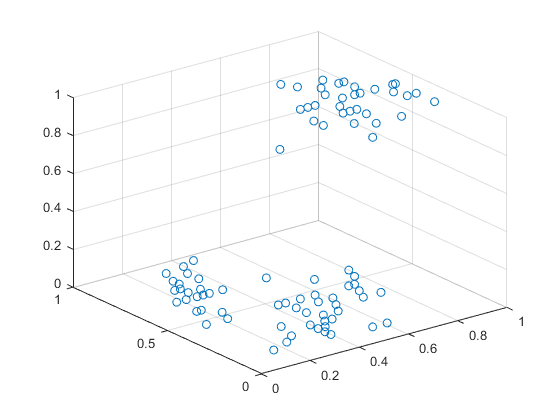

scatter3(xx,yy,zz)


zz=double((output(:,3)))

zz =      1
     0
     0
     0
     0
     0
     0
     0
     1
     1


zz=p1(:,3)

zz =     0.5776
    0.2116
    0.2124
    0.2125
    0.2125
    0.2120
    0.2116
    0.2117
    0.5762
    0.5762


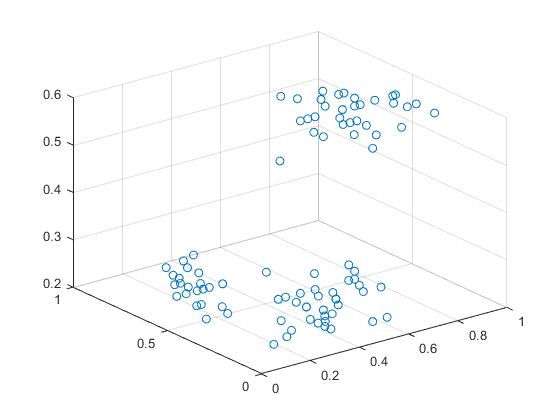


% zz=input(:,3)
% plot3(xx,yy,zz,'.-')
scatter3(xx,yy,zz)

% ii=1
% for re = logspace(-10,-0.5)
% [G, rk] = ttsvd(wplot,re)
% suz=0
% for k=1:4
%     suz = suz + numel(G{k});
% end
% 
% numberelements = numel(wplot)
% 
% numberelements/suz
% recon = tcontract(G);
% 
% 
% ploto(ii) = sum(abs(recon-wplot),'all')/numberelements
% 
% plotosuz(ii)=suz
% ii=ii+1;
% end
% 
% plot(ploto)
% plot(plotosuz)